# 방정식과 연립 방정식

## 방정식 풀기

방정식: $x^2 + 4 - y/4 = 0$

syms x y 
solve(x^2 + x -y/4, y )

$$ans = 4\,x^{2}+4\,x$$

## 연립 방정식 풀기

연립 방정식: $\left\{ \begin{array}{lcc} x^2 y^2 &=& 0 \\ x-y/2 &=& a \end{array}$

syms a
S = solve(x^2*y^2 == 0, x-y/2 == a);
[ S.x S.y]

$$ans = \left(\begin{array}{cc} 0 & -2\,a\\ a & 0 \end{array}\right)$$

연립 방정식: $\left\{ \begin{array}{lcc} x^2+ y^2 &=& 4 \\ x-y/2 &=& 1/2 \end{array}$

eqn1 = x^2 + y^2 == 4;
eqn2 = x - y/2 == 1/2;
S = solve(eqn1, eqn2);
[ S.x, S.y]

$$ans = \left(\begin{array}{cc} \frac{2}{5}-\frac{\sqrt{19}}{5} & -\frac{2\,\sqrt{19}}{5}-\frac{1}{5}\\ \frac{\sqrt{19}}{5}+\frac{2}{5} & \frac{2\,\sqrt{19}}{5}-\frac{1}{5} \end{array}\right)$$

double([ S.x, S.y])

ans =    -0.4718   -1.9436
    1.2718    1.5436


그래프

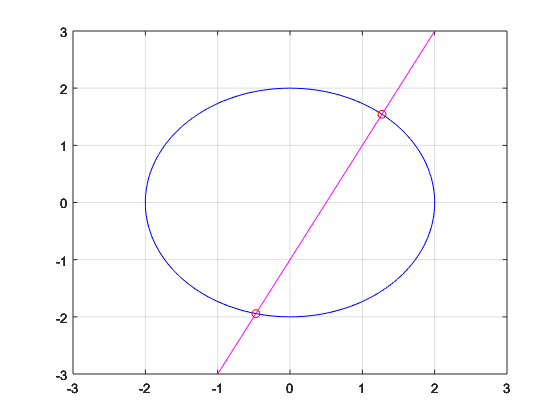

p = axes;
fimplicit(p, eqn1,'b');
axis(3*[-1 1 -1 1]);
hold on; grid on
fimplicit(p, eqn2,'m');
axis(3*[-1 1 -1 1]); 
L = -3:3;
p.XTick = double(L);
p.YTick = double(L);
M = arrayfun(@num2str, L, 'UniformOutput', false);
p.XTickLabel = M;
p.YTickLabel = M;
plot( double(S.x), double(S.y), 'ro');
hold off;

## 부등식

S1 = solve(x^2 - 1 < 0,'Real', true, 'ReturnConditions', true);
S1.conditions
S2 = solve(x^2 - 1 > 0,'Real', true, 'ReturnConditions', true);
S2.conditions
fplot( x^2 -1, [-1.5 1.5]); grid on;

## 상 미분방정식

### 일반 해 구하기

두 번 미분하면 자기 자신이 되는 함수를 구해보겠습니다.


$$y^{''} = y$$
 

syms y(x)
ysol(x) = dsolve( diff(y,2)==y)

$$ysol(x) = C_{2}\,{\mathrm{e}}^{x}+C_{1}\,{\mathrm{e}}^{-x}$$

미분방정식의 해 $y_{sol}(x)$를 미분해서 확인해보지요.

diff(ysol)

$$ans(x) = C_{2}\,{\mathrm{e}}^{x}-C_{1}\,{\mathrm{e}}^{-x}$$

두 번 미분했을 때 원래 함수와 같은지 확인합니다. 

diff(ysol,2)

$$ans(x) = C_{2}\,{\mathrm{e}}^{x}+C_{1}\,{\mathrm{e}}^{-x}$$

### 초기값이 있는 상 미분방정식

$\frac{d^2}{dt^2}y(t) = a^2 y(t)$, $y(0)=b$, $y^{'}(0)=1$

syms y(t) a b
eqn  = diff(y,t,2) == a^2*y;
Dy   = diff(y,t);
cond = [y(0)==b, Dy(0)==1];
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = \frac{{\mathrm{e}}^{a\,t}\,\left(a\,b+1\right)}{2\,a}+\frac{{\mathrm{e}}^{-a\,t}\,\left(a\,b-1\right)}{2\,a}$$

그래프

y1 = subs(subs(ySol,a,1),b,1)

$$y1(t) = {\mathrm{e}}^{t}$$

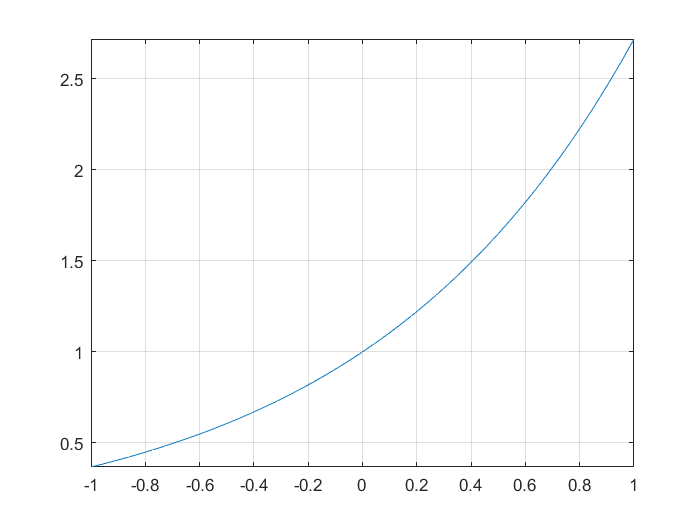

fplot(y1, [-1 1]); grid on